# DATA PROCESSING IN MATLAB

## Data Processing

    It is an important steps in building Machine Learning model. If not done, the ML model wouldn't work effectively.

### Importing Data

    There are two ways of importing data in MATLAB:

- From the `Home` tab `Import Data` option

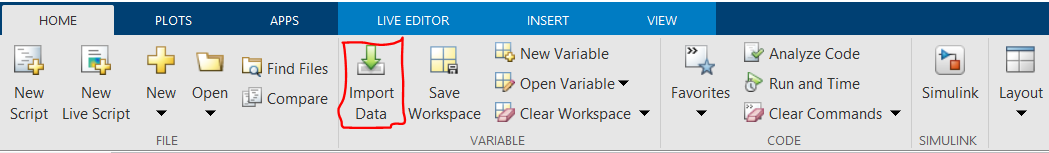

- Reading the data as table, csv, or delimiter method. 

**    Note:**

- If the imported data comprise of missing numerial value, it is replaced with `NaN (Not a number)`

- If the imported data comprise of missing textual value, it is replaced with `'' (Empty string)`

- Machine learning models require `table` data type

% import data
data = readtable("data\data_1.csv","VariableNamingRule","preserve");

% check the first 5 rows of the data
data(1:5,:)

ans = 5×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }    40         72000        {'not liked'}
    {'Asia'  }    25         48000        {'not liked'}
    {'Africa'}    30         54000        {'not liked'}
    {'Asia'  }    35         61000        {'not liked'}
    {'Africa'}    44           NaN        {'Liked'    }


The data above show the opinion of different buyers of a goods based on their location, age, annual salary.

- The opinion is the dependent variable

- The other features are the independent variables.

### Handling Missing Data

There are methods of handling missing data. They are:

- Deleting rows or colums with missing value `rmmissing()`

- Replacing the missing data with the mean of the column

#### **Deleting rows or columns with missing values**

% delete rows of missing value
no_missing_row_data = rmmissing(data)

no_missing_row_data = 8×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }    40         72000        {'not liked'}
    {'Asia'  }    25         48000        {'not liked'}
    {'Africa'}    30         54000        {'not liked'}
    {'Asia'  }    35         61000        {'not liked'}
    {'US'    }    33         58000        {'Liked'    }
    {'US'    }    40         79000        {'Liked'    }
    {'Africa'}    55         83000        {'not liked'}
    {'US'    }    35         67000        {'Liked'    }


% delete columns with missing values
no_missing_col_data = rmmissing(data,2);

% get first 5 rows of the data
no_missing_col_data(1:5,:)

ans = 5×2 table
     Location        Opinion   
    __________    _____________

    {'US'    }    {'not liked'}
    {'Asia'  }    {'not liked'}
    {'Africa'}    {'not liked'}
    {'Asia'  }    {'not liked'}
    {'Africa'}    {'Liked'    }


**Note:**

- Deleting columns or rows can be more dangerous to the data, however, it is not recommended.

- If the data is very large and the missing value is not very significant, you could delete the rows.

- Deleting columns should be generally avoided and should only be considered when numbers of features are many.

- For example, in text categorization and email classification problems.

- By default using `rmmissing()` will remove rows with missing value

- Add `argument 2` to remove column with missing values. 

**Deleting Rows or Columns with Relative percentage of missing value**

- Add the `MinNumMissing `argument to the `rmmissing()`

% import and show the data
data2 = readtable("data\data_2.csv","VariableNamingRule","preserve");
data2(1:5,:)

ans = 5×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }     40        72000        {'not liked'}
    {'Asia'  }     25        48000        {'not liked'}
    {'Africa'}     30          NaN        {'not liked'}
    {'Asia'  }     35        61000        {'not liked'}
    {'Africa'}    NaN          NaN        {'Liked'    }


% 2 -> least number of missing value in a row 
rel_data = rmmissing(data2,'MinNumMissing',2)

rel_data = 9×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }     40        72000        {'not liked'}
    {'Asia'  }     25        48000        {'not liked'}
    {'Africa'}     30          NaN        {'not liked'}
    {'Asia'  }     35        61000        {'not liked'}
    {'US'    }     33        58000        {'Liked'    }
    {'Asia'  }    NaN        52000        {'not liked'}
    {'US'    }     40        79000        {'Liked'    }
    {'Africa'}     55        83000        {'not liked'}
    {'US'    }     35        67000        {'Liked'    }


% 2 -> least number of missing value in a column to be deleted
% N.B: It is not recommended as the necessary features have been deleted
rel_data_del = rmmissing(data2,2,"MinNumMissing",2)

rel_data_del = 10×2 table
     Location        Opinion   
    __________    _____________

    {'US'    }    {'not liked'}
    {'Asia'  }    {'not liked'}
    {'Africa'}    {'not liked'}
    {'Asia'  }    {'not liked'}
    {'Africa'}    {'Liked'    }
    {'US'    }    {'Liked'    }
    {'Asia'  }    {'not liked'}
    {'US'    }    {'Liked'    }
    {'Africa'}    {'not liked'}
    {'US'    }    {'Liked'    }


#### Replacing missing value with Mean

- use `mean()` and add `omitnan` argument to compute the mean.

- Use  `fillmissing() `to fill the missing value

- The `fillmissing` methods are: `constant, next, previous, nearest`, and so on.

% calculate mean omitting NaN
age_mean = mean(data.Age,'omitnan');

% fill missing age with a constant value -> mean
no_missing_age = fillmissing(data.Age,"constant",age_mean);

% copy the data (not necessary)
copy_data = data;
% replace the age column with age with no missing value
copy_data.Age = no_missing_age

copy_data = 10×4 table
     Location      Age      Annual Salary       Opinion   
    __________    ______    _____________    _____________

    {'US'    }        40        72000        {'not liked'}
    {'Asia'  }        25        48000        {'not liked'}
    {'Africa'}        30        54000        {'not liked'}
    {'Asia'  }        35        61000        {'not liked'}
    {'Africa'}        44          NaN        {'Liked'    }
    {'US'    }        33        58000        {'Liked'    }
    {'Asia'  }    37.444        52000        {'not liked'}
    {'US'    }        40        79000        {'Liked'    }
    {'Africa'}        55        83000        {'not liked'}
    {'US'    }        35        67000        {'Liked'    }


% replace missing value in salary column
salary_mean = mean(data.("Annual Salary"), 'omitnan');
no_missing_salary = fillmissing(data.("Annual Salary"),"constant",salary_mean);

format shortG
copy_data.("Annual Salary") = no_missing_salary

copy_data = 10×4 table
     Location      Age      Annual Salary       Opinion   
    __________    ______    _____________    _____________

    {'US'    }        40        72000        {'not liked'}
    {'Asia'  }        25        48000        {'not liked'}
    {'Africa'}        30        54000        {'not liked'}
    {'Asia'  }        35        61000        {'not liked'}
    {'Africa'}        44        63778        {'Liked'    }
    {'US'    }        33        58000        {'Liked'    }
    {'Asia'  }    37.444        52000        {'not liked'}
    {'US'    }        40        79000        {'Liked'    }
    {'Africa'}        55        83000        {'not liked'}
    {'US'    }        35        67000        {'Liked'    }


### Handling missing textual data

Textual data cannot be replaced with the `mean. `Hence, 

% import the data
data3 = readtable("data\data_3.csv","VariableNamingRule","preserve");
data3(1:5,:)

ans = 5×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }    40         72000        {'not liked'}
    {'Asia'  }    25         48000        {0×0 char   }
    {'Africa'}    30         54000        {'not liked'}
    {'Asia'  }    35         61000        {'not liked'}
    {'Africa'}    44           NaN        {'Liked'    }
